# Modifies Example03_08a to include the use of an anonymous function, instead of the subfunction.

fun = @(x) exp(-4*x)*cos(3*pi*x);
x1 = fzero(fun, 0.2)

x1 = 0.1667

x2 = fzero(fun, 0.5)

x2 = 0.5000

x3 = fzero(fun, 0.8)

x3 = 0.8333

fx1 = fun(0.2)

fx1 = -0.1389

fx2 = fun(0.5)

fx2 = -2.4861e-17

fx3 = fun(0.8)

fx3 = 0.0126

# Solves a symmetrical two-spring system

k = 6.8; L = 12; F = 9.2;
equation = @(x) 2*k*(sqrt(L^2+x^2)-L)*x/sqrt(L^2+x^2)-F;
x = fzero(equation, 0)

x = 6.1485

# Demonstrates the precedence order of identifier names.

a = sin(1)

a = 0.8415

sin = 3:5;
b = sin(1)

b = 3

clear
c = sin(1)

c = 0.8415

# Demonstrates program organization. This file, modified from Example03_05c, and Example03_05a constitutes a program.

[mass, spring, damper, delta] = askProperties

mass = 9

spring = 5

damper = 5

delta = 5

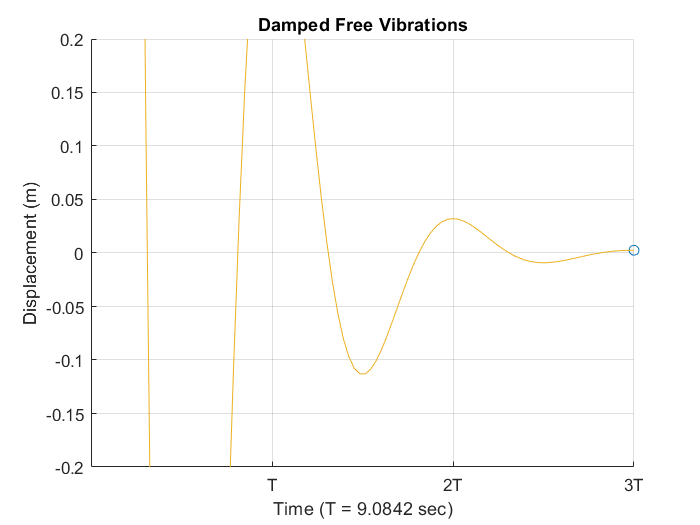

time = 0;
T = getResponse(mass, spring, damper, delta, time);
time = linspace(0, 3*T, 100);
[T, response] = getResponse(mass, spring, damper, delta, time);
plotDisplacement(T, time, response)

# Calculates the maximum deflection of a simply supported beam subject to a uniform load, using the formula in Example02_14.

w = 0.1; h = 0.1; L = 8; E = 210e9; q = 500;
n = 1000; F = q*L/n;
delta = 0;
for k = 1:n
    a = (L/n)*k;
    delta = delta + deflection(w, h, L, E, F, a, L/2);
end
fprintf('Deflection at center is %.4f mm\n', delta*1000)

# Implements the sorting and searching of numbers.

a = []; n = 0;
disp('1. Input numbers and sort')

1. Input numbers and sort


disp('2. Display the list')

2. Display the list


disp('3. Search')

3. Search


disp('4. Save')

4. Save


disp('5. Load')

5. Load


disp('6. Quit')

6. Quit


while 1
    task = input('Enter a task number: ');
    switch task
        case 1
            while 1
                string = input('Enter a number (or stop): ', 's');
                if strcmpi(string, 'stop')
                    break;
                else
                    n = n+1;
                    a(n) = str2num(string);
                end
            end
            a = sort(a);
        case 2
            disp(a)
        case 3
            key = input('Enter a key number: ');
            found = search(a, key);
            if found
                disp(['Index = ', num2str(found)])
            else
                disp('Not found!')
            end
        case 4
            save('Datafile03_13', 'a')
        case 5
            load('Datafile03_13')
            n = length(a);
        case 6
            break
    end
end

     1     2     3     4     5     6     7     8     9



Index = 2
Index = 9


# Creates a function to solve a general statically determinate planar truss problem, given a set of nodal data and member data;

and solves the 3-bar truss problem using the function.

clear, Nodes = [
    1, 1, 0, 0, 0, -1000;
    0, 0, 1, 1, 0,     0;
    2, 0, 0, 1, 0,     0]
Members = [1, 2; 1, 3; 2, 3];
[Nodes, Members] = solveTruss(Nodes, Members)

# Improves Example03_14 to include a text-based user interface, allowing the input of any statically determinate planar truss problem.

clear
Nodes = []; Members = [];
disp(' 1. Input nodal coordinates')

 1. Input nodal coordinates


disp(' 2. Input connecting nodes of members')

 2. Input connecting nodes of members


disp(' 3. Input three supports')

 3. Input three supports


disp(' 4. Input loads')

 4. Input loads


disp(' 5. Print truss')

 5. Print truss


disp(' 6. Solve truss')

 6. Solve truss


disp(' 7. Print results')

 7. Print results


disp(' 8. Save data')

 8. Save data


disp(' 9. Load data')

 9. Load data


disp('10. Quit')

10. Quit


while 1
    task = input('Enter the task number: ');
    switch task
        case 1
            Nodes = inputNodes(Nodes);
        case 2
            Members = inputMembers(Members);
        case 3
            Nodes = inputSupports(Nodes);
        case 4
            Nodes = inputLoads(Nodes);
        case 5
            printTruss(Nodes, Members)
        case 6
            [Nodes, Members] = solveTruss(Nodes, Members);
        case 7
            printResults(Nodes, Members)
        case 8
            saveAll(Nodes, Members)
        case 9
            [Nodes, Members] = loadAll;
        case 10
            break
    end
end

Statically indeterminate!


Truss data not complete


Statically indeterminate!


Error using Example2>inputMembers (line 263)
Error: Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

# function

function [m, k, c, delta] = askProperties
m = input('Enter the mass (kg): ');
k = input('Enter the spring constant (N/m): ');
c = input('Enter the damper constant (N/(m/s)): ');
delta = input('Enter the initial displacement (m): ');
end

function plotDisplacement(T, time, response)
axes('XTick', T:T:3*T, 'XTickLabel', {'T','2T','3T'});
axis([0, 3*T, -0.2, 0.2])
grid on
hold on
comet(time, response)
title('Damped Free Vibrations')
xlabel(['Time (T = ', num2str(T), ' sec)'])
ylabel('Displacement (m)')
end

function [T, x] = getResponse(m, k, c, delta, t)
% Under-damped free vibrations of a mass-spring-damper system
% Input Arguments:
%     m = Mass, a scalar, SI unit: kg
%     k = Spring constant, a scalar, SI unit: N/m
%     c = Damping constant, a scalar, SI unit: N/(m/s)
%     delta = Initial displacement, a scalar, SI unit: m
%     t = Time, a row vector, SI unit: s
% Output Arguments:
%     T = Period, a scalar, SI unit: s
%     x = Displacement, a row vector of the same length of t, SI unit: m
% On Error, it prints a message and returns:
%     T = 0, a scalar
%     x = 0, a scalar
omega = sqrt(k/m);
cC = 2*m*omega;
if c>= cC
    disp('Not an under-damped system!')
    T = 0; x = 0;
    return;
end
omegaD = omega*sqrt(1-(c/cC)^2);
T = 2*pi/omegaD;
x = delta*exp(-c*t/(2*m)).*(cos(omegaD*t)+c/(2*m*omegaD)*sin(omegaD*t));
end

function delta = deflection(w, h, L, E, F, a, x)
I = w*h^3/12;
R = F/L*(L-a);
theta = F*a/(6*E*I*L)*(2*L-a)*(L-a);
delta = theta*x-R*x.^3/(6*E*I)+F/(6*E*I)*((x>a).*((x-a).^3));
end

function out = sort(a)
n = length(a);
for i = n-1:-1:1
    for j = 1:i
        if a(j) > a(j+1)
            tmp = a(j);
            a(j) = a(j+1);
            a(j+1) = tmp;
        end
    end
end
out = a;
end

function found = search(a, key)
n = length(a);
low = 1;
high = n;
found = 0;
while low <= high && ~found
    mid = floor((low+high)/2);
    if key == a(mid)
        found = mid;
    elseif key < a(mid)
        high = mid-1;
    else
        low = mid+1;
    end
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [outNodes, outMembers] = solveTruss(Nodes, Members)
n = size(Nodes,1); m = size(Members,1);
if (m+3) < 2*n
    disp('Unstable!')
    outNodes = 0; outMembers = 0; return
elseif (m+3) > 2*n
    disp('Statically indeterminate!')
    outNodes = 0; outMembers = 0; return
end
A = zeros(2*n, 2*n); loads = zeros(2*n,1); nsupport = 0;
for i = 1:n
    for j = 1:m
        if Members(j,1) == i || Members(j,2) == i
            if Members(j,1) == i
                n1 = i; n2 = Members(j,2);
            elseif Members(j,2) == i
                n1 = i; n2 = Members(j,1);
            end
            x1 = Nodes(n1,1); y1 = Nodes(n1,2);
            x2 = Nodes(n2,1); y2 = Nodes(n2,2);
            L = sqrt((x2-x1)^2+(y2-y1)^2);
            A(2*i-1,j) = (x2-x1)/L;
            A(2*i,  j) = (y2-y1)/L;
        end
    end
    if (Nodes(i,3) == 1)
        nsupport = nsupport+1;
        A(2*i-1,m+nsupport) = 1;
    end
    if (Nodes(i,4) == 1)
        nsupport = nsupport+1;
        A(2*i, m+nsupport) = 1;
    end
    loads(2*i-1) = -Nodes(i,5);
    loads(2*i)   = -Nodes(i,6);
end
forces = A\loads;
Members(:,3) = forces(1:m);
nsupport = 0;
for i = 1:n
    if (Nodes(i,3) == 1)
        nsupport = nsupport+1;
        Nodes(i,7) = forces(m+nsupport);
    end
    if (Nodes(i,4) == 1)
        nsupport = nsupport+1;
        Nodes(i,8) = forces(m+nsupport);
    end
end
outNodes = Nodes; outMembers = Members;
disp('Solved successfully.')
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function output = inputNodes(Nodes)
while 1
    data = input('Enter [node, x, y] or 0 to stop: ');
    if data(1) == 0
        break
    else
        Nodes(data(1),1:2) = data(2:3);
    end
end
output = Nodes;
end

function output = inputMembers(Members)
m = 0;
while 1
    data = input('Enter [node1, node2] or 0 to stop: ');
    if data(1) == 0
        break
    else
        m = m+1;
        Members(m,1:2) = data;
    end
end
output = Members;
end

function output = inputSupports(Nodes)
Nodes(:,3:4) = 0;
for k = 1:3
    data = input('Enter [node, dir] (dir: ''x'' or ''y''): ');
    if data(2) == 'x'
        Nodes(data(1),3) = 1;
    elseif data(2) == 'y'
        Nodes(data(1),4) = 1;
    end
end
output = Nodes;
end

function output = inputLoads(Nodes)
Nodes(:,5:6) = 0;
while 1
    data = input('Enter [node, load-x, load-y] or 0 to stop: ');
    if data(1) == 0
        break
    else
        Nodes(data(1),5:6) = data(2:3);
    end
end
output = Nodes;
end

function printTruss(Nodes, Members)
if (size(Nodes,2)<6 || size(Members,2)<2)
    disp('Truss data not complete'); return
end
fprintf('\nNodal Data\n')
fprintf('Node        x        y  Support-x  Support-y   Load-x   Load-y\n')
for k = 1:size(Nodes,1)
    fprintf('%4.0f%9.2f%9.2f%11.0f%11.0f%9.0f%9.0f\n', k, Nodes(k, 1:6))
end
fprintf('\nMember Data\n')
fprintf('Member  Node1    Node2\n')
for k = 1:size(Members,1)
    fprintf('%4.0f%9.0f%9.0f\n', k, Members(k, 1:2))
end
end

function printResults(Nodes, Members)
if (size(Nodes,2)<8 || size(Members,2)<3)
    disp('Results not available!'), return
end
fprintf('\nReaction Forces\n')
fprintf('Node  Reaction-x  Reaction-y\n')
for k = 1:size(Nodes,1)
    fprintf('%4.0f%12.2f%12.2f\n', k, Nodes(k, 7:8))
end
fprintf('\nMember Forces\n')
fprintf('Member     Force\n')
for k = 1:size(Members,1)
    fprintf('%4.0f%12.2f\n', k, Members(k, 3))
end
end

function saveAll(Nodes, Members)
fileName = input('Enter file name (default Datafile): ', 's');
if isempty(fileName)
    fileName = 'Datafile';
end
save(fileName, 'Nodes', 'Members')
end

function [Nodes, Members] = loadAll
fileName = input('Enter file name (default Datafile): ', 's');
if isempty(fileName)
    fileName = 'Datafile';
end
load(fileName)
end